% ---------------------------------------------------------------
% Example of using the exterior penalty method
% ---------------------------------------------------------------

% Inequality constraints
g1 = @(x) 0.2 - x;
g2 = @(x) x - 4;

% Penalty function
s = @(x) max(0, g1(x))^2 + max(0, g2(x))^2;

% Coefficient update
c = @(ci) ci * 2;

% Objective function to be minimized
f = @(x) 0.2*x + 0.6*sin(8*x) + (0.1*x.^2 - 0.5).^2;
% Initial point
x0 = -4;
% Maximum number of iterations
Nmax = 100;
% Stopping tolerance
eps = 0.001;
% Initial penalty coefficient
c1 = 1/4;

%% Run the penalty method
[x_min, N] = penalty_method(x0, c1, c, eps, Nmax, f, s)

x_min = 0.5867

N = 3

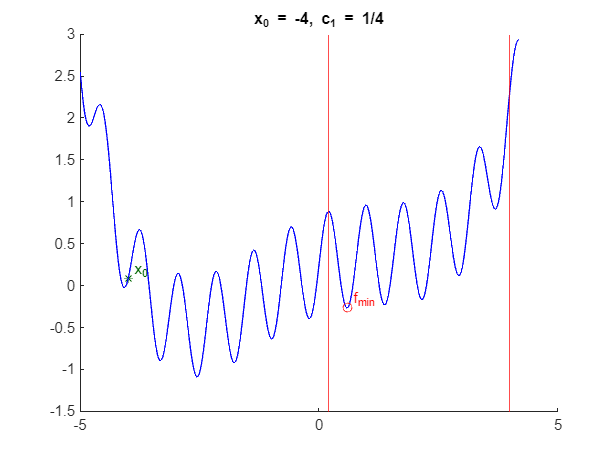


%% Plotting: full domain with constraints highlighted
t = -5:0.01:4.2;
F = f(t);

figure; hold on;
xline(0.2, 'red');
xline(4, 'red');
plot(x0, f(x0), '*', 'Color', [0 0.4 0]);
text(x0+0.1, f(x0)+0.1, 'x_0', 'Color', [0 0.4 0]);
plot(t, F, 'blue');
plot(x_min, f(x_min), 'ro');
text(x_min+0.1, f(x_min)+0.1, 'f_{min}', 'Color', 'r');
title('x_0 = -4, c_1 = 1/4');
hold off;

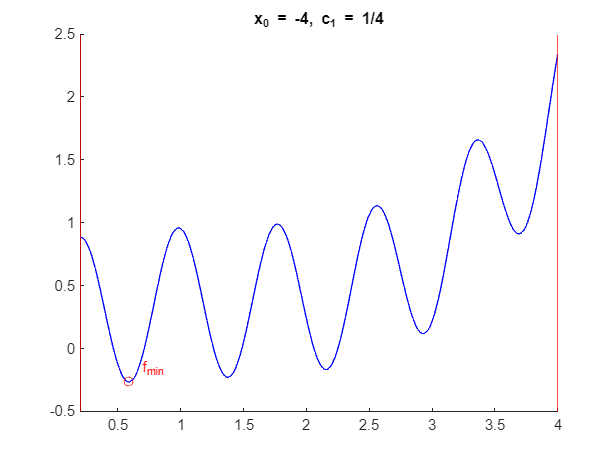


% Plotting: zoom on feasible region
t = 0:0.01:4.2;
F = f(t);

figure; hold on;
xlim([0.2, 4]);
xline(0.2, 'red');
xline(4, 'red');
plot(t, F, 'blue');
plot(x_min, f(x_min), 'ro');
text(x_min+0.1, f(x_min)+0.1, 'f_{min}', 'Color', 'r');
title('x_0 = -4, c_1 = 1/4');
hold off;

% ---------------------------------------------------------------
% Example of using the interior penalty method
% ---------------------------------------------------------------

% Penalty function
s = @(x) -log(x + 1.7) - log(-x);

% Coefficient update
c = @(ci) ci / 2;

% Objective function
f = @(x) 0.2*x + 0.4*sin(4*x) + (0.1*x.^2 - 0.4).^2;

% Initial point inside feasible region
x0 = -1.3;
% Maximum number of iterations
Nmax = 100;
% Stopping tolerance
eps = 0.001;
% Initial penalty coefficient
c1 = 0.7;

% Run the penalty method
[x_min, N] = penalty_method(x0, c1, c, eps, Nmax, f, s)

x_min = -0.4352

N = 9

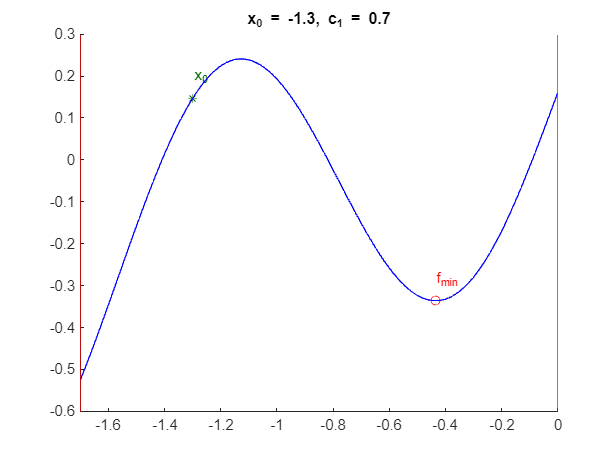


% Plotting
t = -1.7:0.01:0;
F = f(t);

figure; hold on;
xlim([-1.7, 0]);
xline(-1.7, 'red');
xline(0, 'red');
title('x_0 = -1.3, c_1 = 0.7');

plot(x0, f(x0), '*', 'Color', [0 0.4 0]);
text(x0, f(x0)+0.05, 'x_0', 'Color', [0 0.4 0]);

plot(t, F, 'blue');
plot(x_min, f(x_min), 'ro');
text(x_min, f(x_min)+0.05, 'f_{min}', 'Color', 'r');

hold off;

% ---------------------------------------------------------------
% 2D optimization using interior (barrier) method
% ---------------------------------------------------------------

clear; close all; clc;

% Circle center x
xc = 0.7;
% Circle center y
yc = 0.0;
% Circle radius
R = 0.4;

% Objective function
f2 = @(x1, x2) 0.3*x1 + 0.1*x2 + (-3.5 + 0.5*x1.^2 + 0.5*x2.^2).^2 + 100*x1 .* exp(-x1.^2 - x2.^2);
f = @(x) f2(x(1), x(2));

% Constraint: points inside circle
g = @(x) (x(1) - xc).^2 + (x(2) - yc).^2 - R^2;

% Barrier grows to infinity at boundary
s = @(x) -log(-g(x));
% Initial barrier coefficient
c1 = 1/2;
% Coefficient update
c_fun = @(ci) ci / 2;

% Starting point inside feasible region
P0 = [0.6; 0.1];
% Stopping tolerance
eps = 1e-3;
% Maximum iterations
Nmax = 50;

% Run method
[x_min, N] = penalty_method(P0, c1, c_fun, eps, Nmax, f, s)

x_min =     0.3009
   -0.0008


N = 4

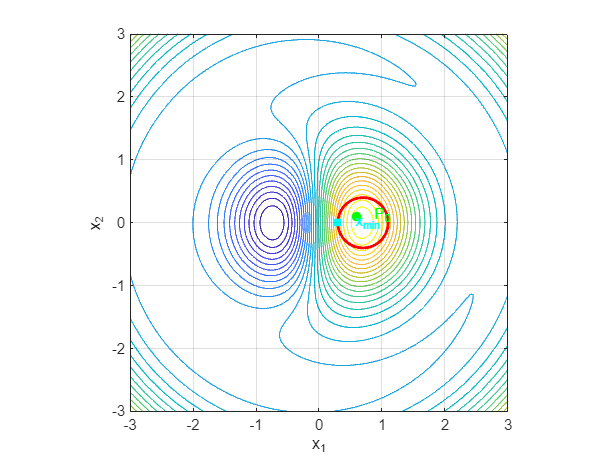


% Plotting
x1 = linspace(-3, 3, 400);
x2 = linspace(-3, 3, 400);
[X1, X2] = meshgrid(x1, x2);
Z = f2(X1, X2);

figure;
% Contour of objective function
contour(X1, X2, Z, 30);
hold on;

% Feasible region (circle)
th = linspace(0, 2*pi, 300);
plot(xc + R*cos(th), yc + R*sin(th), 'r', 'LineWidth', 2);

% Initial point
plot(P0(1), P0(2), 'go', 'MarkerFaceColor', 'g');
text(P0(1), P0(2), '  P_0', 'Color','g');

% Found minimum
plot(x_min(1), x_min(2), 'cs', 'MarkerFaceColor','c');
text(x_min(1), x_min(2), '  x_{min}', 'Color','c');

xlabel('x_1');
ylabel('x_2');
axis equal;
grid on;
hold off;

% ---------------------------------------------------------------
% 2D optimization using exterior penalty method
% ---------------------------------------------------------------

clear; close all; clc;

% Circle center x
xc = 0.7;
% Circle center y
yc = 0.0;
% Circle radius
R  = 0.4;

% Objective function
f2 = @(x1, x2) 0.3*x1 + 0.1*x2 + (-3.5 + 0.5*x1.^2 + 0.5*x2.^2).^2 + 100*x1 .* exp(-x1.^2 - x2.^2);
f = @(x) f2(x(1), x(2));

g = @(x) (x(1) - xc).^2 + (x(2) - yc).^2 - R^2;

% Exterior penalty function
s = @(x) max(0, g(x)).^2;  
% Initial penalty coefficient
c1 = 1;
% Penalty coefficient update
c_fun = @(ci) ci * 2;

% Starting point
P0 = [-0.75; 0.0];
% Stopping tolerance
eps = 1e-3;
% Maximum iterations
Nmax = 50;

% Run exterior penalty method
[x_min, N] = penalty_method(P0, c1, c_fun, eps, Nmax, f, s)

x_min =     0.2991
   -0.0008


N = 17

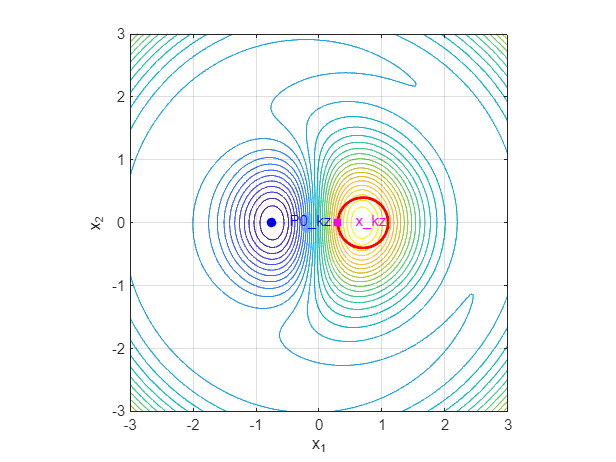


% Plotting
x1 = linspace(-3, 3, 400);
x2 = linspace(-3, 3, 400);
[X1, X2] = meshgrid(x1, x2);
Z = f2(X1, X2);

figure;
% Contours of the objective function
contour(X1, X2, Z, 30);
hold on;

% Feasible region: circle boundary
th = linspace(0, 2*pi, 300);
plot(xc + R*cos(th), yc + R*sin(th), 'r', 'LineWidth', 2);

% Initial point
plot(P0(1), P0(2), 'bo', 'MarkerFaceColor','b');
text(P0(1), P0(2), '  P0\_kz', 'Color','b');

% Found minimum
plot(x_min(1), x_min(2), 'ms', 'MarkerFaceColor','m');
text(x_min(1), x_min(2), '  x\_kz', 'Color','m');

xlabel('x_1');
ylabel('x_2');
axis equal;
grid on;
hold off;